# Problema 4

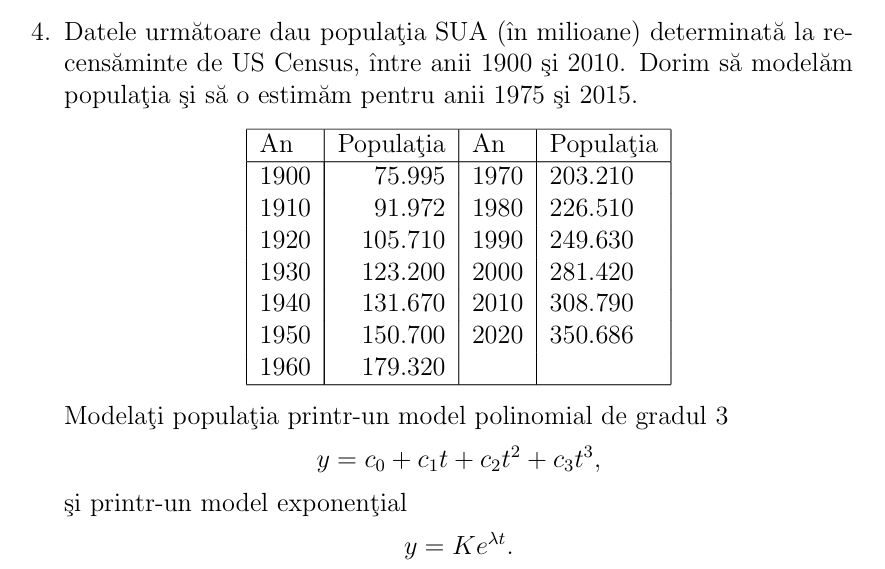

ani = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010 2020];
populatie = [75.995 91.972 105.710 123.200 131.670 150.700 ...
             179.320 203.210 226.510 249.630 281.420 308.790 350.686];

t0 = 1900;         % punct de referinta
t = ani - t0       % lucram cu ani relativi: 1900 -> 0, 1910->10 si asa mai departe

t =      0    10    20    30    40    50    60    70    80    90   100   110   120


% MODEL POLINOMIAL DE GRAD 3

% Construim matricea A pentru forma: y = c0 + c1*t + c2*t^2 + c3*t^3
A_poly = [ones(length(t), 1), t', (t').^2, (t').^3]

A_poly =            1           0           0           0
           1          10         100        1000
           1          20         400        8000
           1          30         900       27000
           1          40        1600       64000
           1          50        2500      125000
           1          60        3600      216000
           1          70        4900      343000
           1          80        6400      512000
           1          90        8100      729000


% A_pol*c=populatie, aflam c
c = A_poly \ populatie'  % coeficientii polinomului

c =    77.4826
    1.2209
    0.0058
    0.0000



% Estimari pentru anii 1975 si 2015
ani_estim = [1975, 2015];
t_estim = ani_estim - t0;
% Ne folosim de coeficientii (c) pe care ii introducem in polinom pentru a
% prezice populatia
y_estim_poly = c(1) + c(2)*t_estim + c(3)*t_estim.^2 + c(4)*t_estim.^3;

fprintf('Model POLINOMIAL grad 3:\n');

Model POLINOMIAL grad 3:


fprintf('Populatia estimata in 1975: %.2f milioane\n', y_estim_poly(1));

Populatia estimata in 1975: 211.49 milioane


fprintf('Populatia estimata in 2015: %.2f milioane\n\n', y_estim_poly(2));

Populatia estimata in 2015: 330.29 milioane



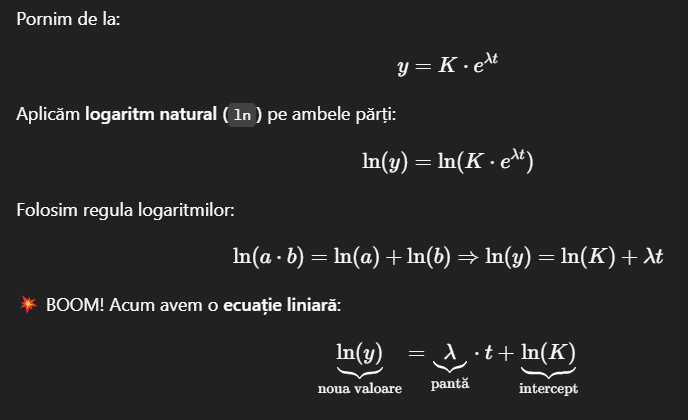

% MODEL EXPONENȚIAL: y = K * exp(lambda * t)
% y-> populatia, t-> anii, K si lambda sunt necunoascute

% ln(y) = ln(K) + lambda * t
ln_pop = log(populatie);
% A_exp * params = ln_pop
A_exp = [t', ones(length(t), 1)]

A_exp =      0     1
    10     1
    20     1
    30     1
    40     1
    50     1
    60     1
    70     1
    80     1
    90     1


params = A_exp \ ln_pop'

params =     0.0124
    4.3995



lambda = params(1);   % panta dreptei
ln_K   = params(2);   % interceptul
K      = exp(ln_K);   % transformăm ln_K în K


% Estimari
y_estim_exp = K * exp(lambda * t_estim);

fprintf('Model EXPONENȚIAL:\n');

Model EXPONENȚIAL:


fprintf('Populatia estimata in 1975: %.2f milioane\n', y_estim_exp(1));

Populatia estimata in 1975: 207.04 milioane


fprintf('Populatia estimata in 2015: %.2f milioane\n\n', y_estim_exp(2));

Populatia estimata in 2015: 340.60 milioane



% Calculul erorilor pentru comparatie

y_poly_all = A_poly * c;
y_exp_all = K * exp(lambda * t');

eroare_poly = sum((populatie' - y_poly_all).^2);
eroare_exp = sum((populatie' - y_exp_all).^2);

fprintf('Eroare totala POLINOMIAL: %.4f\n', eroare_poly);

Eroare totala POLINOMIAL: 130.3599


fprintf('Eroare totala EXPONENTIAL: %.4f\n', eroare_exp);

Eroare totala EXPONENTIAL: 498.6040



if eroare_poly < eroare_exp
    fprintf('\nModelul POLINOMIAL este mai bun (eroare mai mica).\n');
else
    fprintf('\nModelul EXPONENȚIAL este mai bun (eroare mai mica).\n');
end


Modelul POLINOMIAL este mai bun (eroare mai mica).
